clear

tic

%logistic Regression Simulation
% set seed to same default value
num=500;
beta0set=zeros(1,num);
beta1set=zeros(1,num);
for times=1:num
    if mod(times,10)==0
        times
    end
    % set true linear coefficients
    beta0tru = -10; 
    beta1tru = 0.3;
    % select indepedent x values
    dx = 5; 
    x = (10:dx:60)';
    n = length(x);
    % generate dichotomous values
    p = 1./(1 + exp(-beta0tru - beta1tru.*x));
    y=binornd(ones(n, 1), p);
    % Grid search values 
    beta0min =-14; 
    beta0max = -3; 
    beta1min = -4; 
    beta1max = 4; 
    beta0del = 0.01; 
    beta1del = 0.01;
    beta0 = (beta0min:beta0del:beta0max)';
    beta1 = (beta1min:beta1del:beta1max)';
    m0 = size(beta0, 1); 
    m1 = size(beta1, 1);
    % try all beta0, beta1 values 
    maxLL = -10^6; 
    LL = ones(m0, m1);
    beta0hat = 0; 
    beta1hat = 0;
    for i = 1 : m0
        for j = 1 : m1
            LL(i, j) = sum(y.*(beta0(i, 1) + beta1(j, 1)*x)) ... 
            - sum(log(1 + exp(beta0(i, 1) + beta1(j, 1)*x)));
            if (LL(i, j) > maxLL)
                beta0hat = beta0(i, 1);
                beta1hat = beta1(j, 1);
                maxLL = LL(i, j);
            end
        end
    end
    beta0set(times)=beta0hat;
    beta1set(times)=beta1hat;
end

times = 10

times = 20

times = 30

times = 40

times = 50

times = 60

times = 70

times = 80

times = 90

times = 100

times = 110

times = 120

times = 130

times = 140

times = 150

times = 160

times = 170

times = 180

times = 190

times = 200

times = 210

times = 220

times = 230

times = 240

times = 250

times = 260

times = 270

times = 280

times = 290

times = 300

times = 310

times = 320

times = 330

times = 340

times = 350

times = 360

times = 370

times = 380

times = 390

times = 400

times = 410

times = 420

times = 430

times = 440

times = 450

times = 460

times = 470

times = 480

times = 490

times = 500


toc

历时 3781.093117 秒。


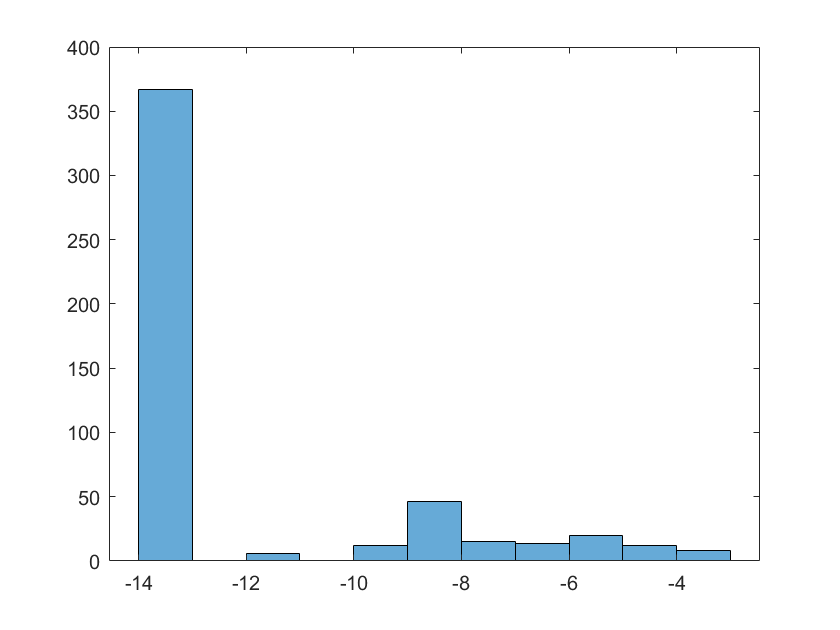


histogram(beta0set)

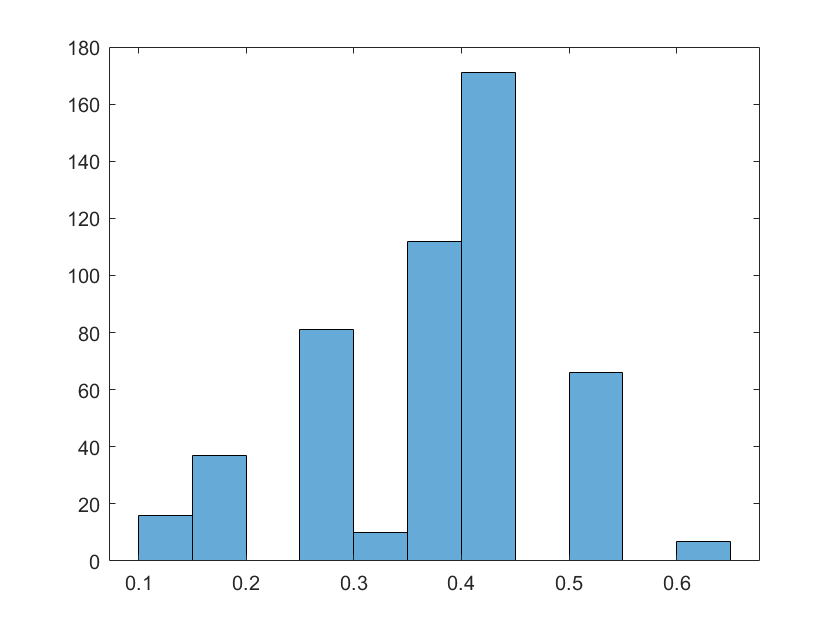

histogram(beta1set)


mean_beta_0 = mean(beta0set)

mean_beta_0 = -12.2077

mean_beta_1 = mean(beta1set)

mean_beta_1 = 0.3742


standard_deviation_beta_0 = std(beta0set)

standard_deviation_beta_0 = 3.1165

standard_deviation_beta_1 = std(beta1set)

standard_deviation_beta_1 = 0.1071


pset = 1./(1 + exp(-beta0set - beta1set.*x));

pplus2s = 1./(1 + exp(-beta0set + 2*sqrt(standard_deviation_beta_0) ...
    - (beta1set + 2*sqrt(standard_deviation_beta_1)).*x));

pmi2s = 1./(1 + exp(-beta0set - 2*sqrt(standard_deviation_beta_0) ...
    - (beta1set - 2*sqrt(standard_deviation_beta_1)).*x));

a=mean(pset,2)

a =     0.0043
    0.0100
    0.0291
    0.1052
    0.3169
    0.6313
    0.8608
    0.9540
    0.9841
    0.9938


b=mean(pplus2s,2)

b =     0.0495
    0.4086
    0.9822
    0.9999
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


c=mean(pmi2s,2)

c = 	1.0e+-3 *

    0.2210
    0.0203
    0.0024
    0.0005
    0.0003
    0.0002
    0.0002
    0.0001
    0.0001
    0.0001


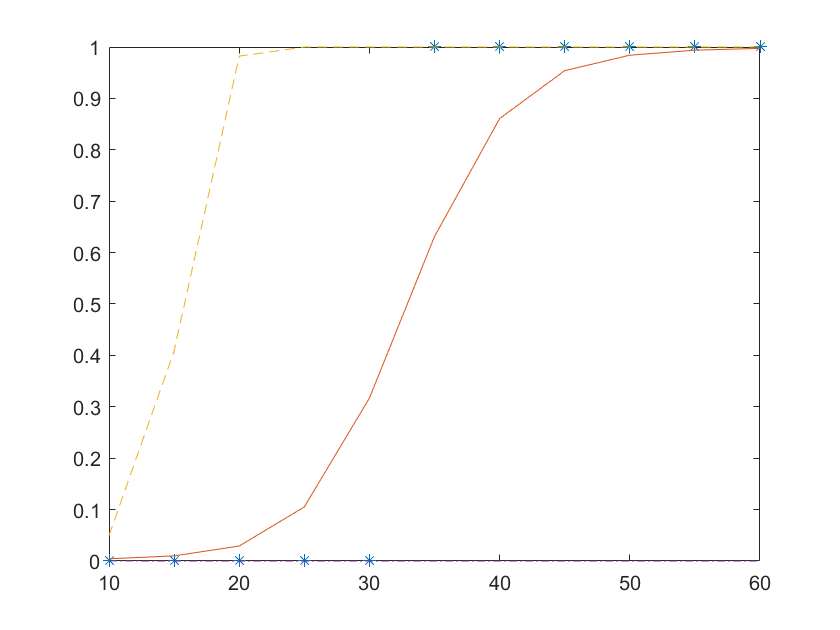


plot(x,y,'*')
hold on
plot(x,a)
plot(x,b,'--')
plot(x,c,'-.')